# EEC

Ajutar la señal segun su ganacia y base, para que todas las señales sean iguales

load Subject03_1_edfm.mat;
signal={'Fp1', 'Fp2', 'F3', 'F4', 'F7', 'F8', 'T3', 'T4', 'C3', 'C4', 'T5', 'T6', 'P3', 'P4', 'O1', 'O2', 'Fz', 'Cz', 'Pz', 'A2-A1'};
gain=[483.323050073, 671.574501217, 686.799079279, 497.264834745, 502.950010752, 208.43093346, 680.616810088, 650.637497668, 587.807244429, 674.614285538, 814.500355889, 713.789595935, 363.816312372, 561.011534572, 508.96555227, 514.810372092, 665.136283161, 489.997098224, 436.24110144, 1146.47381671];
base=[-4481, -1499, 464, 1907, 2628, 174, 108, -1238, -501, 191, -5490, -649, -1026, 2726, -1824, 3705, -1027, -1086, 439, 176];
x=val(1:20,:);
for i=1:20
    x(i,:)=(x(i,:)-base(i))/gain(i);
end

## Representacion en tiempo y en frecuencia

N=length(val(1,:));
ts=0.002; %ts=(3*60+2)/N;
fs=1/ts;
n=linspace(0,N-1,N);
t=n*ts;
f=n/(N*ts);

#### Representacion en tiempo

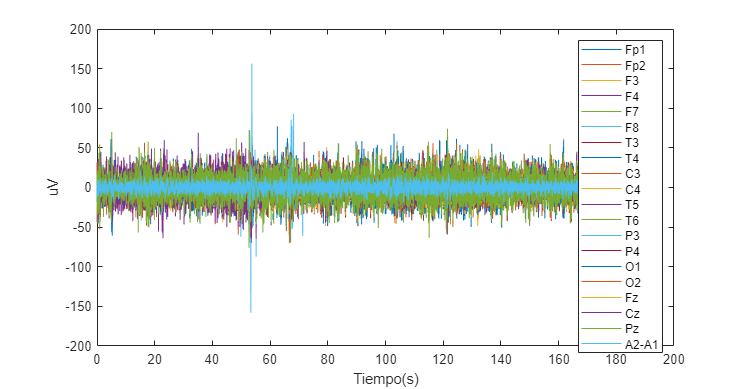

subplot(111);plot(t,x); ylabel("uV"); xlabel("Tiempo(s)"); legend(signal);

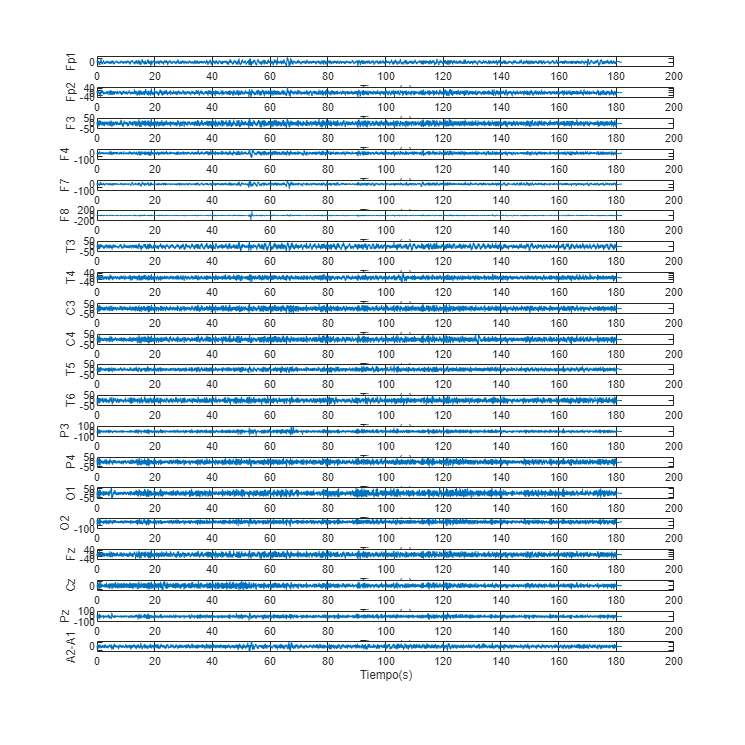

for i=1:20
    subplot(20,1,i);plot(t,x(i,:)); ylabel(signal(i)); xlabel("Tiempo(s)"); set(gcf,'Position',[1000 1000 5000 5000]);
end

#### Representacion en frecuencia analogica

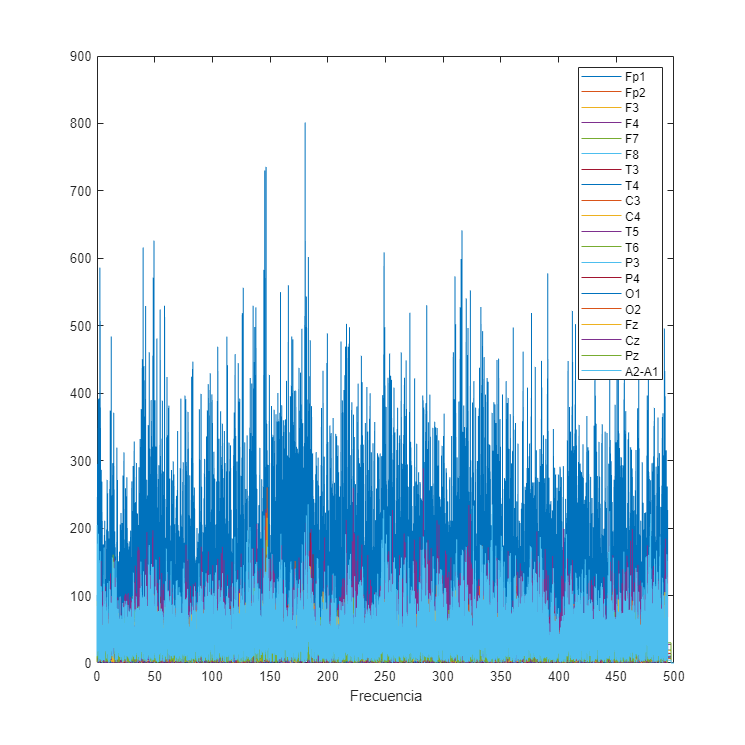

Xa=fft(x);
subplot(111);plot(f,abs(Xa)); xlabel("Frecuencia"); legend(signal);

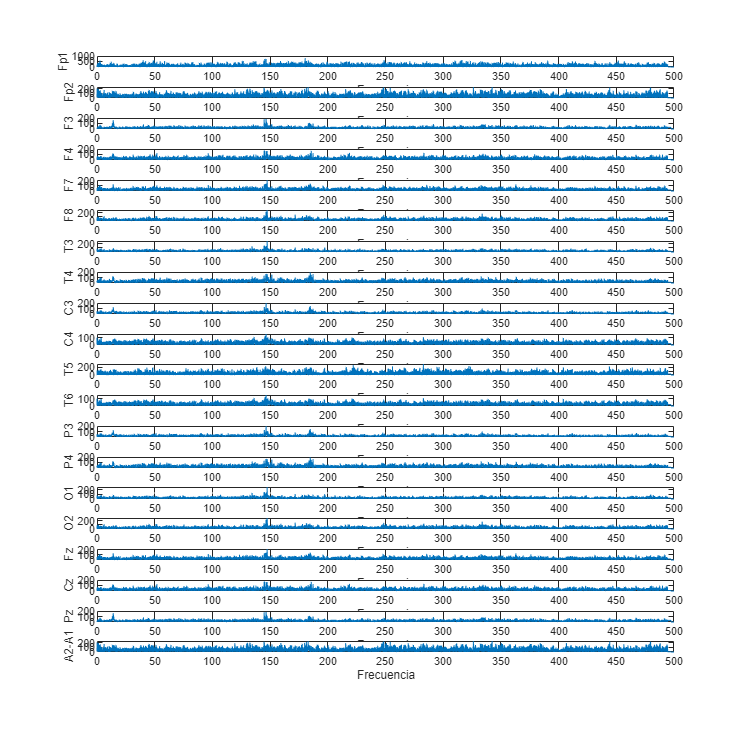

for i=1:20
    subplot(20,1,i);plot(f,abs(Xa(i,:))); ylabel(signal(i)); xlabel("Frecuencia");set(gcf,'Position',[1000 1000 5000 5000]);
end

#### Representacion en frecuencia discreta normalizada

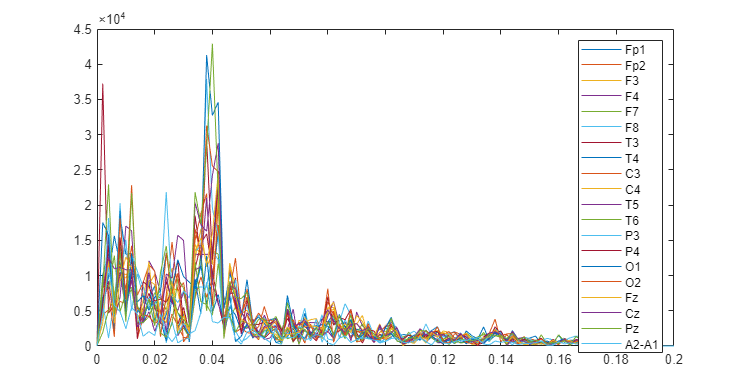

w=linspace(0,pi,501);
Xd=fDTFT(x.*hamming(N)',n,w);
subplot(111);plot(w/pi,abs(Xd));axis([0,0.2,0,45000]); legend(signal);

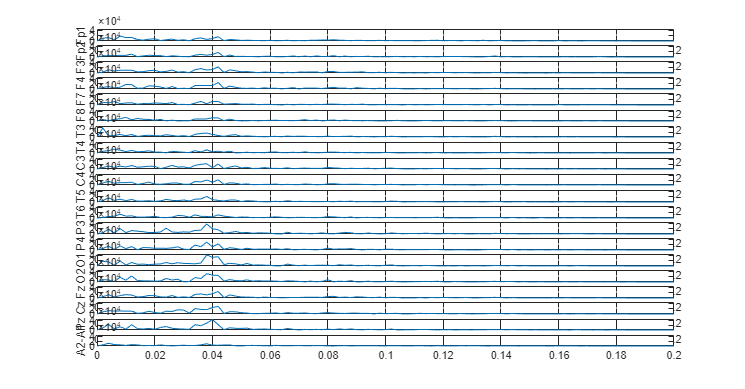

for i=1:20
    subplot(20,1,i);plot(w/pi,abs(Xd(i,:))); ylabel(signal(i)); axis([0,0.2,0,45000]); 
end

## Procesado de señal (procesar por wavelets)

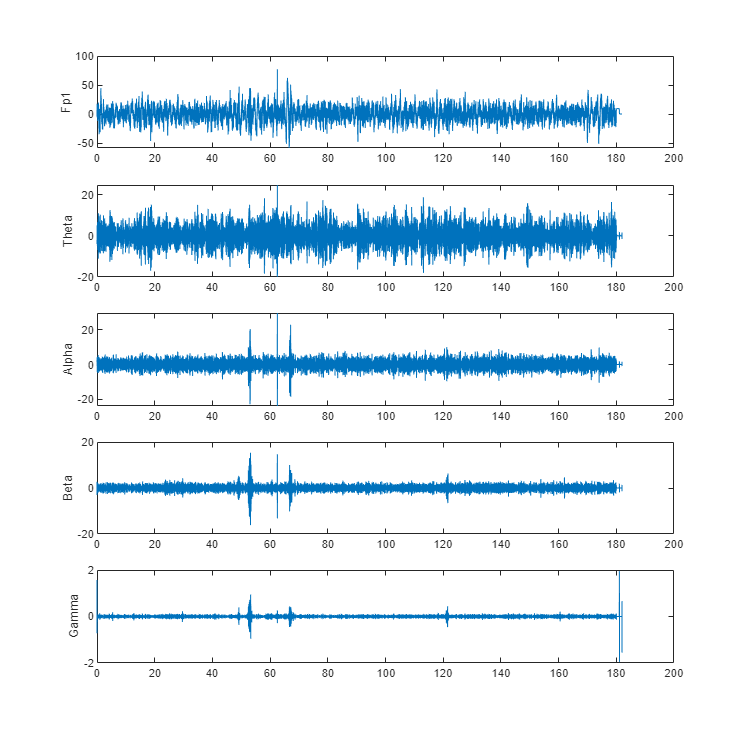

wt=modwt(x(1,:),'db8');
wtrec=zeros(size(wt));
wtrec(2,:)=wt(2,:);
x1gamma=imodwt(wtrec,'db8');
wtrec=zeros(size(wt));
wtrec(3,:)=wt(3,:);
x1beta=imodwt(wtrec,'db8');
wtrec=zeros(size(wt));
wtrec(4,:)=wt(4,:);
x1alpha=imodwt(wtrec,'db8');
wtrec=zeros(size(wt));
wtrec(5,:)=wt(5,:);
x1theta=imodwt(wtrec,'db8');
subplot(511);plot(t,x(1,:)); ylabel("Fp1");...
    subplot(512);plot(t,x1theta); ylabel("Theta");...
    subplot(513);plot(t,x1alpha); ylabel("Alpha");...
    subplot(514);plot(t,x1beta); ylabel("Beta");...
    subplot(515);plot(t,x1gamma); ylabel("Gamma"); set(gcf,'Position',[1000 1000 5000 5000]);

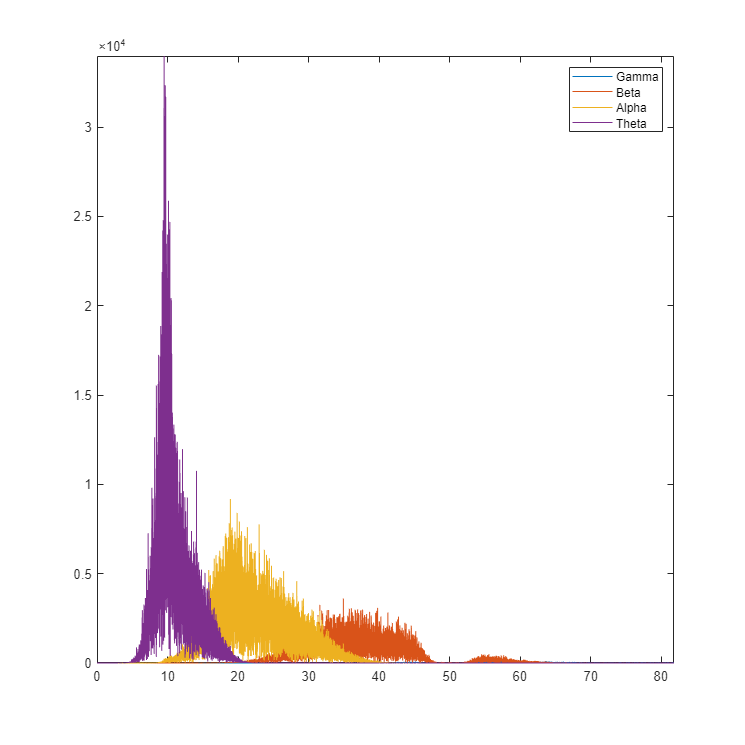

X1gamma=fft(x1gamma);
X1beta=fft(x1beta);
X1alpha=fft(x1alpha);
X1theta=fft(x1theta);
subplot(111);plot(f,abs(X1gamma),f,abs(X1beta),f,abs(X1alpha),f,abs(X1theta)); axis([0 50 0 Inf]); legend('Gamma','Beta','Alpha','Theta');

Luego probar cosas https://www.youtube.com/watch?v=Rl7ELFwh5qw